A script to test the S cerevisiae IMM904 model and ensure that it's behaving properly when executing different enzyme expression modes

%Script params
%currentdir = pwd;
%rundir = 'C:\sync\biomes\cellulose\optima\temp';


%load base model as 'model', put it in layout_default
load('C:\sync\biomes\models\Scerevisiae_iMM904.mat')
model_default = model;
layout = createLayout();
layout = addModel(layout,model);
layout = setInitialPop(layout,'1x1');
layout.params.maxCycles = 10;
layout.params.timeStep = 1;
layout.params.defaultDiffConst = 0;
layout_default = layout;


%ensure the model is capable of growth in its normal state

layout.media_amt(1:end) = 1;
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

cd(currentdir);
%Growth with all media supplied: Passed!

%Find a minimalistic media recipe: Growth should happen iff glucose is supplied
layout = layout_default;

%expect no growth when no media added
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script


%expect no growth when only glucose is provided
layout = setInitialMedia(layout,'glc__D_e',1);
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script


%expect no growth when media is added sans glucose
layout = setInitialMedia(layout,'glc__D_e',0);
media = {'co2_e', 'fe2_e', 'h_e', 'h2o_e', 'k_e', 'na1_e', 'nh4_e', 'o2_e', 'pi_e', 'so4_e'};
for i = 1 : length(media)
 layout = setInitialMedia(layout,media{i},1);
end
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script



%apply glc and media, expect growth
layout = setInitialMedia(layout,'glc__D_e',1);
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

%Pass, assuming error code 10005 == no growth

%find the minimal media set for this model
layout = layout_default;
%media = {'glc__D_e', 'co2_e', 'fe2_e', 'h_e', 'h2o_e', 'k_e', 'na1_e', 'nh4_e', 'o2_e', 'pi_e', 'so4_e'};
media = {'glc__D_e', 'nh4_e', 'o2_e', 'pi_e', 'so4_e'};
for i = 1 : length(media)
 layout = setInitialMedia(layout,media{i},1);
end
layout.params.writeMediaLog = true;
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

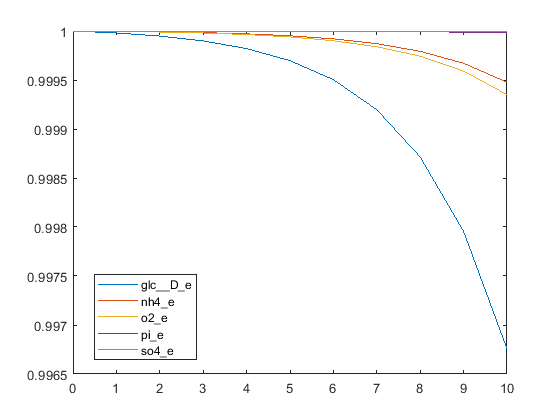

medialog = parseMediaLog('C:\sync\biomes\cellulose\optima\temp\media.m',media);
plotMediaTimecourse(medialog,media);

%Pass.   media = {'glc__D_e', 'nh4_e', 'o2_e', 'pi_e', 'so4_e'};

%check the fluxes to find if all amino acids are being produced
layout = layout_default;
layout.params.writeFluxLog = true;
media = {'glc__D_e', 'nh4_e', 'o2_e', 'pi_e', 'so4_e'};
for i = 1 : length(media)
 layout = setInitialMedia(layout,media{i},1);
end
rc(layout)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

fluxes = parseFluxLog('C:\sync\biomes\cellulose\optima\temp\flux.m');

biomets = find(model.S(:,1577));
model.mets(biomets);
t= table();
t.metname = model.mets(biomets);
t.s = model.S(biomets,1577);
fluxes(fluxes.rxn==1577,:)

ans = 10×6 table
    t     x    y    model    rxn      flux  
    __    _    _    _____    ____    _______

     1    1    1    1        1577    0.28787
     2    1    1    1        1577    0.28787
     3    1    1    1        1577    0.28787
     4    1    1    1        1577    0.28787
     5    1    1    1        1577    0.28787
     6    1    1    1        1577    0.28787
     7    1    1    1        1577    0.28787
     8    1    1    1        1577    0.28787
     9    1    1    1        1577    0.28787
    10    1    1    1        1577    0.28787


%BUILDING A PORPORTIONAL MODEL
model = model_default;
model = addMetabolitesToRxn(model,{'biomass_pseudo'},find(model.c),1);

%Show that biomass_pseudo is being created properly
model_temp = model;
model = addExchangeRxn(model,{'biomass_pseudo'});
rm(model)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


res =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

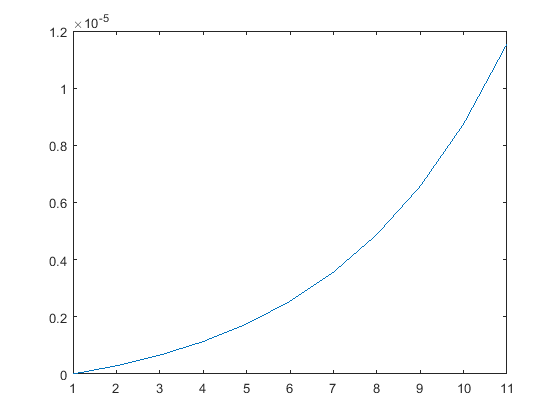

medialog = parseMediaLog('C:\sync\biomes\cellulose\optima\temp\media.m',{'biomass_pseudo'});
plot(medialog.amt)

title('biomass_pseudo production');
%model = model_temp;

model = model_temp;
%add the enzyme
v = getOptVars();
v.enzByWeight = false;
v.alpha = .01;
[stoich, metnames] = getEnzymeStoich(v);
model = addReaction(model,'create_enzyme',metnames,stoich,0);
es = v.alpha / (1 - v.alpha);
model = addReaction(model,'secrete_enzyme',{'enzyme_c','biomass_pseudo','enzyme_e'},[-es,-1,es],0);
model = addExchangeRxn(model,{'enzyme_e'});
biomassobj = find(model.c);

%test that enzyme production works by setting create_enzyme to be the objective and biomass reaction
% % %model.c(stridx('create_enzyme',model.rxns)) = 1;
% % %model = setBiomassRxn(model,'create_enzyme',1);
% % %%%model = addExchangeRxn(model,{'enzyme_c'});
%PASS: it works if you add an exchange reaction for enzyme_c 

%test that producing biomass_pseudo is OK by making an exchange/objective rxn for it
% % % model = addExchangeRxn(model,{'biomass_pseudo'});
% % % model.c(stridx('EX_biomass_pseudo',model.rxns)) = 1;
% % % model = setBiomassRxn(model,stridx('EX_biomass_pseudo',model.rxns));
%PASS. Growth occurs

%test that secretion works by setting secrete_enzyme rxn to be the objective and biomass reaction
model.c(stridx('secrete_enzyme',model.rxns)) = 1;
model = setBiomassRxn(model,'secrete_enzyme');


model.c(biomassobj) = 0;
model = refreshCsense(model);
rm(model)

Executing COMETS in the directory C:\sync\biomes\cellulose\optima\temp


ans =     '
     C:\sync\biomes\cellulose\optima\temp>java -Xmx2048m -classpath C:\Users\mquintin\workspace\dist\\comets_2.5.13.jar;C:/Users/mquintin/workspace/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/jmatio.jar;C:\Users\mquintin\workspace\dist/lib/x64/glpk-java.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/gluegen-rt-natives-windows-amd64.jar;C:\Users\mquintin\workspace\dist/lib/jogamp-all-platforms/jar/jogl-all-natives-windows-amd64.jar;C:\gurobi751\win64/lib/gurobi.jar -Djava.library.path=C:\Users\mquintin\workspace\dist/lib;C:\Users\mquintin\workspace\dist/lib/x64;C:\gurobi751\win64;C:\gurobi751\win64/lib/;C:\gurobi751\win64/bin edu.bu.segrelab.comets.Comets -loader edu.bu.segrelab.comets.fba.FBACometsLoader -script comets_script

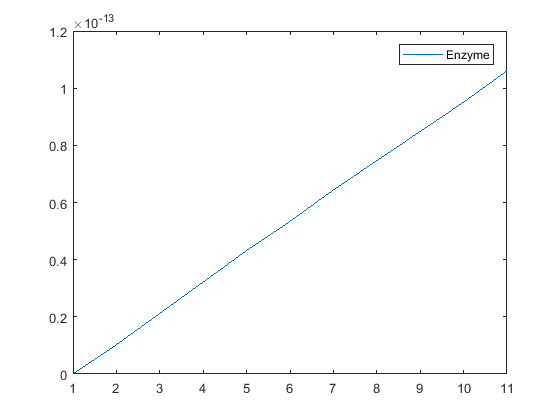


%model.c(stridx('secrete_enzyme',model.rxns)) = 1;
%model.c(biomassobj) = 0;
%model = setBiomassRxn(model,biomassobj);
%rm(model)
medialog = parseMediaLog('C:\sync\biomes\cellulose\optima\temp\media.m',{'enzyme_e',});
plot(1:11,medialog.amt(medialog.met == 1));
legend('Enzyme');

function res = rc(layout)
    %just a wrapper to change folders quickly
    currentdir = pwd;
    rundir = 'C:\sync\biomes\cellulose\optima\temp';
    cd(rundir);
    res = runComets(layout);
    cd(currentdir);
end

function res = rm(model)
    %a wrapper to quickly build a layout and execute a model
    layout = createLayout();
    layout = addModel(layout,model);
    layout = setInitialPop(layout,'1x1');
    layout.params.maxCycles = 10;
    layout.params.timeStep = 1;
    layout.params.defaultDiffConst = 0;
    media = {'glc__D_e', 'nh4_e', 'o2_e', 'pi_e', 'so4_e'};
    for i = 1 : length(media)
        layout = setInitialMedia(layout,media{i},1);
    end
    layout.params.writeMediaLog = true;
    res = rc(layout);
end